# Reduced order model for the soft robot

clearvars;
close all
clc

## Import data

See mat file in [https://drive.google.com/drive/u/0/folders/1z2GUDNL4oAfWPNIhuZ-e4d7AcqhTlSBM](https://drive.google.com/drive/u/0/folders/1z2GUDNL4oAfWPNIhuZ-e4d7AcqhTlSBM) 

load dataDecayObs
rdof = 3;

nTraj = size(oData,1);
odof = 3;
ndof = size(Xsnapshots,1)/2;
outdofs = [1 2 3];

## Train and test data

indTest = [1 3 5 7 9 11 13 15];
indTrain = setdiff(1:nTraj,indTest);

## Truncate trajectories

sliceInt = [0.14 2.6];
oDataTrunc = sliceTrajectories(oData, sliceInt);
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Train Geometery of the SSM

SSMDim = 2*rdof;
obsDim = 2*odof;
SSMOrder = 3;
IMInfo = IMGeometry(oDataTrunc(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',yDataTrunc(indTrain,:));
IMInfoInv = IMGeometry(yDataTrunc(indTrain,:),obsDim, SSMOrder,'reducedCoordinates',oDataTrunc(indTrain,:));

Evaluate parametrization error

% Compute and display error
% Train error
errorGeoTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTrain(iTraj),:));
    errorGeoTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end

Store map in the same variables

sVar = {'map', 'polynomialOrder', 'dimension', 'nonlinearCoefficients', 'phi', 'exponents', 'H'};
for iVar = 1:length(sVar)
    IMInfo.chart.(sVar{iVar}) = IMInfoInv.parametrization.(sVar{iVar});
end

## Train Dynamics of the SSM (mechanical style - continuous dynamical system)

ROMOrder = 3;
RDInfo = IMDynamicsFlow(yDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -3.4956 +16.7981i
  -3.5890 +17.1300i
  -3.6572 +18.3668i




yRec = advectRD(RDInfo, yDataTrunc);

normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 1.8632

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 0.7931

## Evaluate global error

% Train error
errorGloTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yRec(indTrain(iTraj),:));
    errorGloTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGloTrain

errorGloTrain =     0.7036    0.6659    0.6006    1.2933    1.0619    0.5630    1.3373    0.4321    0.6140    1.6250    0.4133    0.5870    0.8753    0.7896    0.6846    1.3056    0.4069    0.6825    1.0624    1.2251    0.3931    0.4420    0.4542    0.6166    0.4003    0.8026    0.4576    0.5973    0.8445    1.3573    0.4223    0.8030   12.0096    5.8998    6.5708    1.9572    0.7238    0.7723    0.4207    0.7931    4.8530   10.5211    2.1456    4.7926


meanErrorGloTrain = mean(errorGloTrain)

meanErrorGloTrain = 1.7268

## Understand which mode is more responsbile for what motion

outdofsMat = zeros(3,2*ndof);
output_node = 1354;
outdofsPS =  3*output_node + [1 2 3];

for ii = 1:3
outdofsMat(ii,outdofsPS(ii)) = 1;
end

redDynLinearPart = RDInfo.reducedDynamics.coefficients(:,1:2*rdof);
redStiffnessMat = -redDynLinearPart(rdof+1:end,1:rdof);
[UconsRedDyn,w2] = eig(redStiffnessMat);
[consFreqs,pos] = sort(sqrt(diag(w2))); UconsRedDyn = UconsRedDyn(:,pos);
[consFreqs abs(RDInfo.eigenvaluesLinPartFlow(1:3))];
Ucons = [UconsRedDyn zeros(rdof); zeros(rdof) UconsRedDyn];
Vcons = V*Ucons;
abs(RDInfo.eigenvaluesLinPartFlow(1:3))

ans =    17.1579
   17.5020
   18.7274


modesDir = outdofsMat*Vcons(:,1:rdof)

modesDir =     0.0381    0.0194   -0.0183
    0.0142   -0.0402   -0.0062
    0.0217    0.0049    0.0445


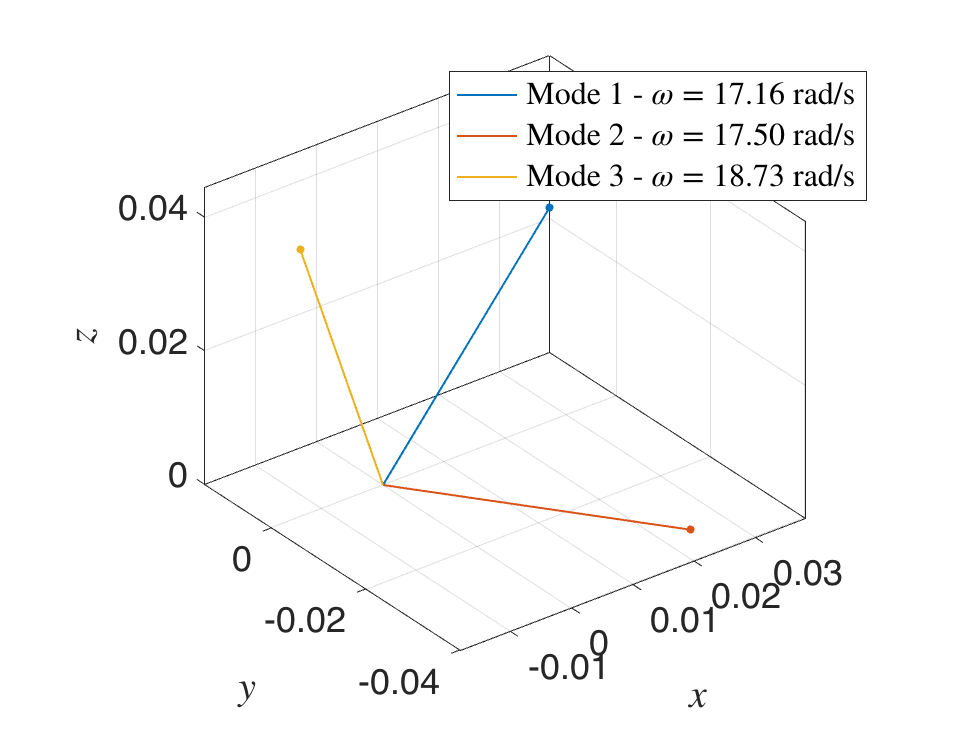

% Plots mode direction
customFigure; classicColors = colororder;
for ii = 1:3
plot3([0 modesDir(1,ii)],[0 modesDir(2,ii)],[0 modesDir(3,ii)],'Linewidth',1,'Color',classicColors(ii,:))
plot3([modesDir(1,ii)],[modesDir(2,ii)],[modesDir(3,ii)],'.','MarkerSize',12,'Color',classicColors(ii,:),'HandleVisibility','off')
end
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
legend(['Mode 1 - $\omega =  ' num2str(round(abs(RDInfo.eigenvaluesLinPartFlow(1)),2)) '$' ' rad/s'],...
    ['Mode 2 - $\omega =  ' num2str(round(abs(RDInfo.eigenvaluesLinPartFlow(2)),2)) '0$' ' rad/s'],...
    ['Mode 3 - $\omega =  ' num2str(round(abs(RDInfo.eigenvaluesLinPartFlow(3)),2)) '$' ' rad/s'],'interpreter','latex')
view(3)
axis equal

% Hence mode 1 is mainly along x, mode 2 along y and mode 3 along z.

## Control


$$H_{\textrm{red}} ={\mathrm{V}}^{\top } M^{-1} H$$


Hred = transpose(V(1:ndof,1:rdof))*(M\H);

normsModalForcing = mean((transpose(V(1:ndof,1:rdof))*(M\H)).^2,1)

normsModalForcing = 	1.0e+03 *

    3.6165    3.6851    2.7069    3.6295


normsNonModalForcing = mean(((eye(ndof)-V(1:ndof,1:rdof)*transpose(V(1:ndof,1:rdof)))*(M\H)).^2,1)

normsNonModalForcing = 	1.0e+03 *

    1.8746    1.5411    1.3337    1.2016



Rauton = RDInfo.reducedDynamics.map;
R = @(t,p,u) Rauton(p) + [zeros(rdof,size(Hred,2)); Hred]*u;
C = IMInfo.parametrization.map;
W = IMInfo.chart.map;

## Integrate the model with inputs

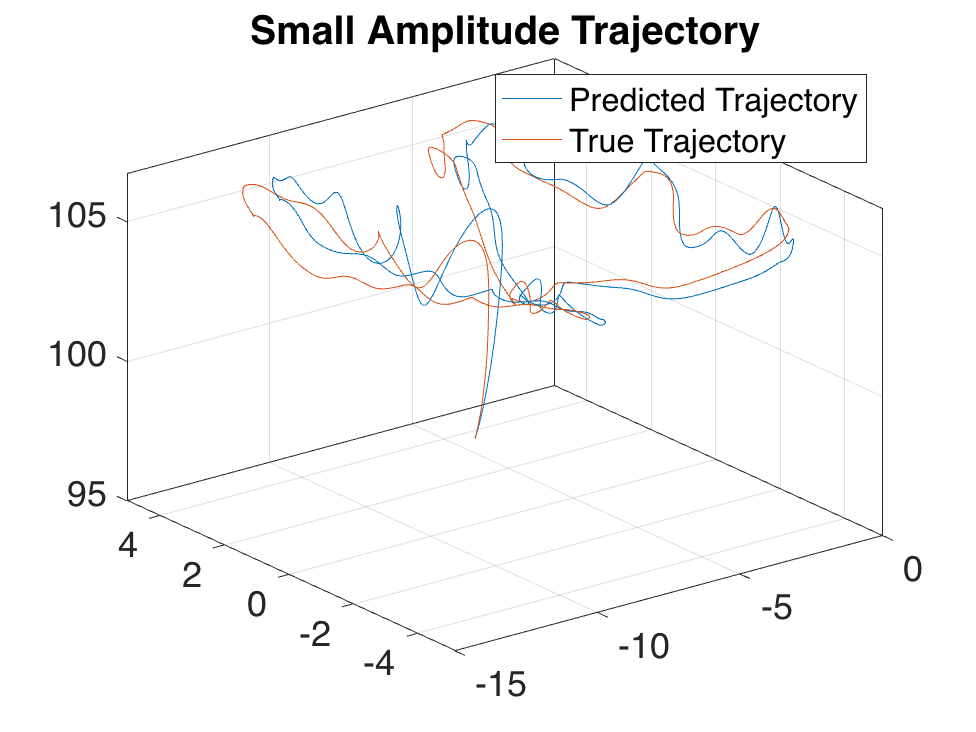

% Load the controls and actual trajectories for figure eight
uFigureEight = readmatrix("../system_data/u_small.csv");
z = readmatrix("../system_data/z_small.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';
z_eq = [z_eq, 0, 0, 0];

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1);
z_true = z(4:end, :);


uFun = @(t) transpose(interp1(t_span, uFigureEight, t));
[~,yTraj] = ode45(@(t,p) R(t,p,uFun(t)),t_span,zeros(2*rdof,1));
yTraj = transpose(yTraj);
oTraj = C(yTraj) + z_eq.';

% Visualize the trajectory
customFigure; 
plot3(oTraj(1, :), oTraj(2, :), oTraj(3, :)); 
plot3(z_true(1, :), z_true(2, :), z_true(3, :)); 
legend('Predicted Trajectory', 'True Trajectory')
title('Small Amplitude Trajectory')
view(3)

## Define big amplitude trajectory

% Load the controls and actual trajectories for figure eight
uFigureEight = readmatrix("../system_data/u_big.csv");
z = readmatrix("../system_data/z_big.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';
z_eq = [z_eq, 0, 0, 0];

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1);

## Learn control matrix

% Currently using big figure 8 trajectory
z_eight_true = [z(4:end, :); z(1:3, :)];
z_eight_shift = z_eight_true - z_eq.';
U_eight = uFigureEight.';
% Comment this out
% U = U_eight(:, 4:end-3);
% z_shift = z_eight_shift;

% Importing from training data
load diamond_train_full
y = y'; U = u';
z_true = [y(4:end, :); y(1:3, :)];
z_shift = z_true - z_eq.';
t_span = [t, t_span(2:end)+t(end)];
U = [U U_eight(:, 2:end)];
U = U(:, 4:end-3);
z_shift = [z_shift z_eight_shift(:, 2:end)];

Xbar = IMInfo.chart.map(z_shift);
[dXbarDt,Xbar,t] = finiteTimeDifference(Xbar, t_span, 3); % Truncates X_bar 3 places on each side

dXbarDt_ROM = Rauton(Xbar); % Evaluate derivative of ROM dynamics for each Xbar

% Set options for ridgeRegression
varargin = {'R_PolyOrd', [3], 'style', 'default'};
nargin = 5;

L2 = 1 + 0 * exp(0*t);
% [B_learn,l_opt,Err] = ridgeRegression(U, dXbarDt(4:end, :) - dXbarDt_ROM(4:end, :), L2, [], 0);
% B_learn = [zeros(rdof,size(B_learn,2)); B_learn]*u;

% Learn whole B matrix
[B_learn,l_opt,Err] = ridgeRegression(U, dXbarDt - dXbarDt_ROM, L2, [], 0);
R = @(t,p,u) Rauton(p) + B_learn*u;


## Integrate model with inputs (Big amplitude)

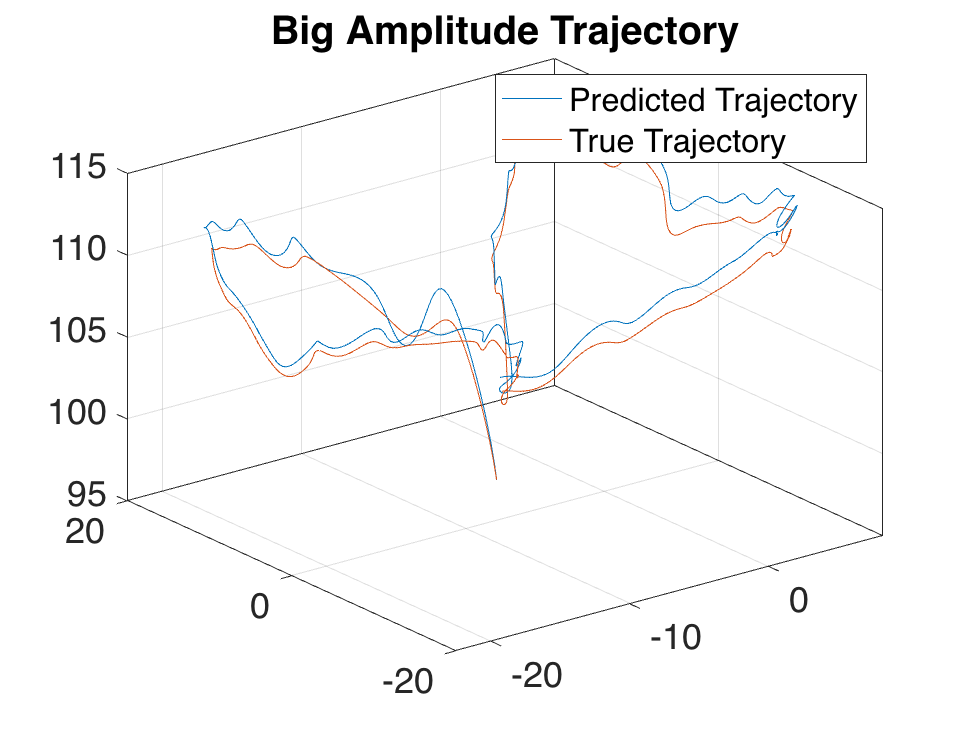

z_true = z(4:end, :);
t_span = linspace(0, T, N+1);
uFun = @(t) transpose(interp1(t_span, uFigureEight, t));
[~,yTraj] = ode45(@(t,p) R(t,p,uFun(t)),t_span,zeros(2*rdof,1));
yTraj = transpose(yTraj);
oTraj = C(yTraj) + z_eq.';

% Visualize the trajectory
customFigure; 
plot3(oTraj(1, :), oTraj(2, :), oTraj(3, :)); 
plot3(z_true(1, :), z_true(2, :), z_true(3, :)); 
legend('Predicted Trajectory', 'True Trajectory')
title('Big Amplitude Trajectory')
view(3)


RMSE = sum(sqrt(mean((oTraj(1:3, :) - z_true).^2))) / size(oTraj, 2)

RMSE = 0.6153

## Visualize SSM

syms x1 x2
% xbar = [x1; x2; zeros(4,1)];
R_ord2 = @(x1, x2) Rauton([x1; x2; zeros(4,1)]);
W_bar = matlabFunction(W([x1; x2; zeros(4,1)])); % use matlabFunction to vectorize

numPts = 100;
% eta1 = linspace(-5000,5000,numPts);
% eta2 = linspace(-3000,3000,numPts);
eta1 = linspace(-3000,3000,numPts);
eta2 = linspace(-3000,3000,numPts);
[X1,X2] = meshgrid(eta1, eta2);

Plot full trajectory

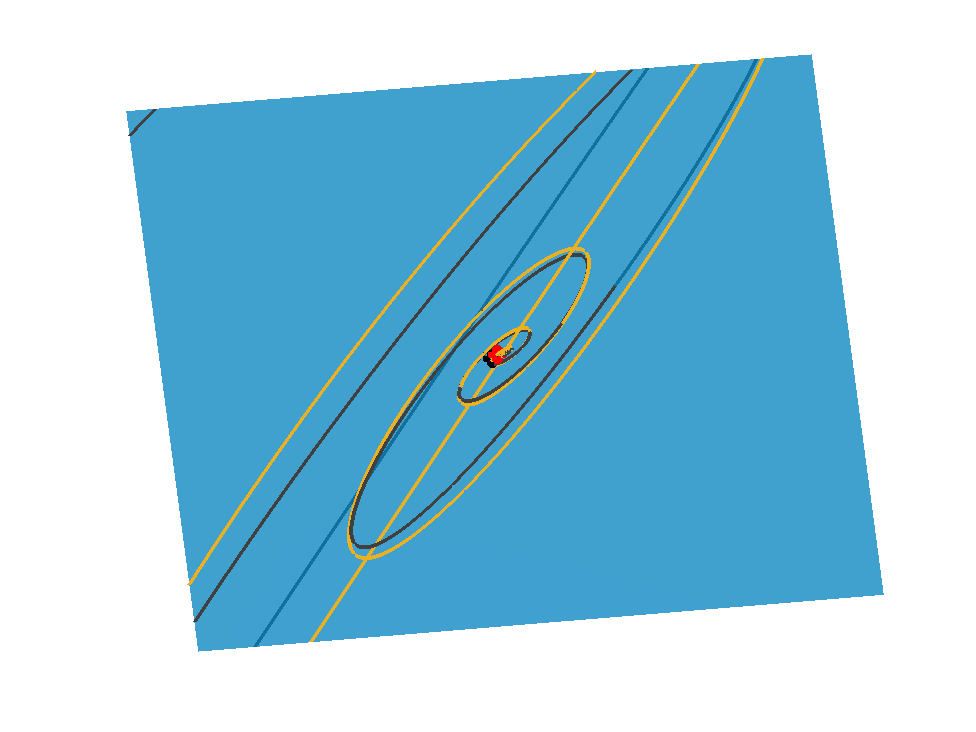

% Plot SSM for slice (x_3,...,x_n = 0)
dofDesired = 3;
zobs_y = W_bar(X1, X2);
figure;
if dofDesired == 1
    surf(X1, X2, zobs_y(dofDesired:dofDesired + size(X1, 1) - 1,:));
else
    dofElement = (dofDesired-1)*size(X1, 1) + 1;
    surf(X1, X2, zobs_y(dofElement:dofElement + size(X1, 1) - 1,:));
end
shading interp
colormap winter
alpha 0.75;
hold on;

% Plot Full trajectory (6, 10, 32
trajIdx = 15;
desTraj = yData{trajIdx, 2};
desObsTraj = W(desTraj);
% Truncate first point to exaggerate off-manifold
idxInitial = 10;
desTraj = desTraj(:, idxInitial:end);
desObsTraj = desObsTraj(:, idxInitial:end);
plot3(desTraj(1,:), desTraj(2, :), desObsTraj(dofDesired, :), 'Linewidth', 2, 'color', [0.25 0.25 0.25]); %light blue

% Plot trajectory on SSM
eta0 = yDataTrunc(trajIdx, :); % Starting too far causes integration issues
etaDes = advectRD(RDInfo, eta0);
xbarDes = etaDes{1,2}(1:2, :);
zonSSMDes = W_bar(xbarDes(1, :), xbarDes(2, :));
plot3(xbarDes(1,:), xbarDes(2, :), zonSSMDes(dofDesired, :), 'Linewidth', 2, 'color', '#EDB120'); %orange

fullPlot = plot3(NaN, NaN, NaN, 'o','color', 'black', 'Linewidth', 10);
onSSMPlot = plot3(NaN, NaN, NaN, 'o','color', 'red', 'Linewidth', 10);
idxStartSSMDyn = 97; %Originally 107
for k = 1:10:floor(size(desTraj, 2)/2)
    set(fullPlot, 'XData', desTraj(1,k), 'YData', desTraj(2,k), 'ZData', desObsTraj(dofDesired, k));
    if k >= idxStartSSMDyn
        kROM = k-idxStartSSMDyn+1;
        set(onSSMPlot, 'XData', xbarDes(1,kROM), 'YData', xbarDes(2,kROM), 'ZData', zonSSMDes(dofDesired, kROM));
        if k >= idxStartSSMDyn + 600
            xlim([-172 172])
            ylim([-229 229])
            zlim([-859628 859628])
            view([-96 90])
        end
    else
        set(onSSMPlot, 'XData', xbarDes(1,1), 'YData', xbarDes(2,1), 'ZData', zonSSMDes(dofDesired, 1));
    end
    axis off
    drawnow
end

Plot truncated trajecory

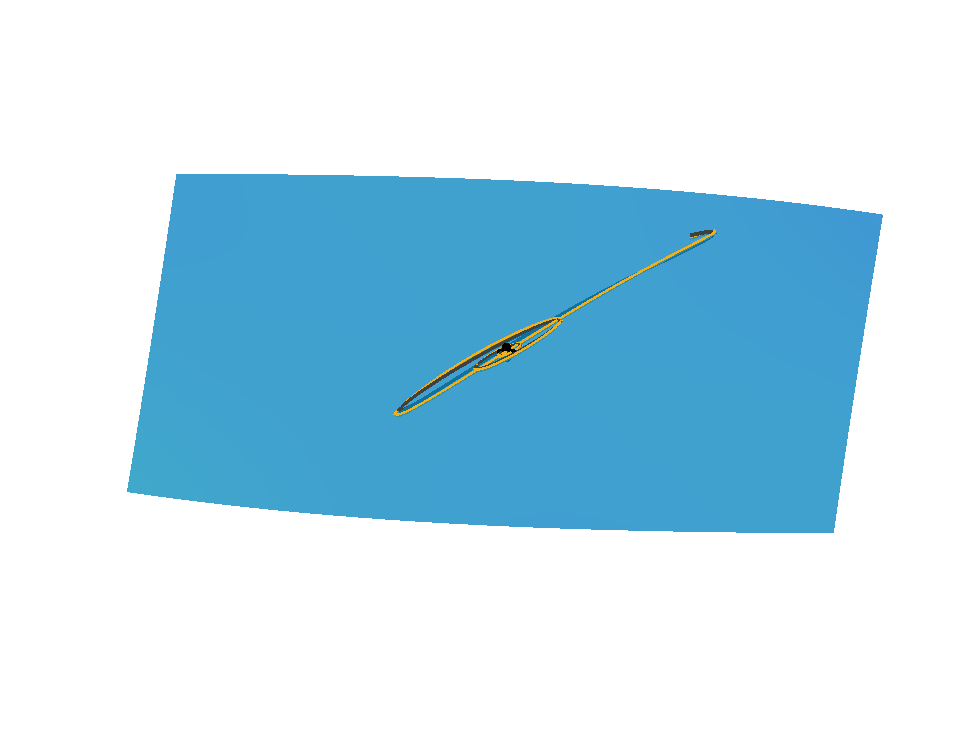

figure;
if dofDesired == 1
    surf(X1, X2, zobs_y(dofDesired:dofDesired + size(X1, 1) - 1,:));
else
    dofElement = (dofDesired-1)*size(X1, 1) + 1;
    surf(X1, X2, zobs_y(dofElement:dofElement + size(X1, 1) - 1,:));
end
shading interp
colormap winter
alpha 0.75;
hold on;

% Update axes
xlim([-1157 1157])
ylim([-1542 1542])
zlim([-5783149 5783149])
view([-86 56])

% Plot Truncated trajectory
trajIdx = 15;
desTruncTraj = yDataTrunc{trajIdx, 2};  
desTruncObsTraj = W(desTruncTraj);
plot3(desTruncTraj(1,:), desTruncTraj(2, :), desTruncObsTraj(dofDesired, :), 'Linewidth', 2, 'color', [0.25 0.25 0.25]); %orange

% Plot trajectory on SSM
plot3(xbarDes(1,:), xbarDes(2, :), zonSSMDes(dofDesired, :), 'Linewidth', 2, 'color', '#EDB120'); %light green

truncPlot = plot3(NaN, NaN, NaN, 'o','color', 'black', 'Linewidth', 4);
onSSMPlot = plot3(NaN, NaN, NaN, 'o','color', 'red', 'Linewidth', 4);
for k = 1:10:floor(size(desTraj, 2)/2)
    set(truncPlot, 'XData', desTruncTraj(1,k), 'YData', desTruncTraj(2,k), 'ZData', desTruncObsTraj(dofDesired, k));
    set(onSSMPlot, 'XData', xbarDes(1,k), 'YData', xbarDes(2,k), 'ZData', zonSSMDes(dofDesired, k));
    axis off
    drawnow
end
hold on;